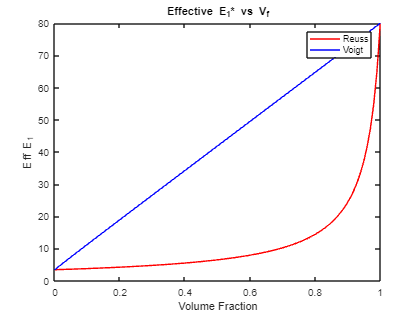

% Voigt

clear all;
format long e
t = linspace(0,1,100);
%
% Volume fraction
syms Vf
%    Vf = 0.5;
Vm = 1.0 - Vf;
%
% Now calculate the stiffness matrix of fibre
%
%
% Fibre is transversely isotropic with following properties in MPa
%
E1 = 80;
E2 = 80;
E3 = E2;
%
G12 = 33.33;
G13 = 33.33;
%
G23 = 33.33;
%
nu_12 = 0.2;
nu_13 = nu_12;
%
nu_23 = E2/(2.0 * G23) - 1.0;
%
nu_21 = nu_12 * E2/E1;
nu_31 = nu_13 * E3/E1;
nu_32 = nu_23 * E3/E2;
%
% Initialization
%
s = zeros(6,6);
stiff_fibre = zeros(6,6);
stiff_matrix = zeros(6,6);
%
s(1,1)=1.0/E1;
s(2,2)=1.0/E2;
s(3,3)=1.0/E3;
%
s(1,2)=-nu_21/E2;
s(1,3)=-nu_31/E3;
%
s(2,1)=-nu_21/E2;
s(2,3)=-nu_32/E3;
%
s(3,1)=-nu_13/E1;
s(3,2)=-nu_23/E2;
%
% Following order is according order in Abaqus
%
s(4,4)=1.0/G12;
s(5,5)=1.0/G13;
s(6,6)=1.0/G23;
%
stiff_fibre = inv(s);
%
% Calculate the stiffness matrix of matrix
%
% Matrix is isotropic with following properties
%
E0 = 3.35;
XNU = 0.35;
%
XX = E0 * (1.0 - XNU)/((1.0 - 2.0 * XNU)*(1.0 + XNU));
YY = E0 * XNU/((1.0 - 2.0 * XNU)*(1.0 + XNU));
ZZ = E0 /(2.0 * (1.0 + XNU));
%
for I = 1:3
    for J = 1:3
        stiff_matrix(I,J) = YY;
    end
    stiff_matrix(I,I) = XX;
    stiff_matrix(I+3,I+3) = ZZ;
end
stiff_matrix;


%%%%%%%%%%%%%%%%%%%%%%%%%
%  Voigt Approximation  %
%%%%%%%%%%%%%%%%%%%%%%%%%

% Effective stiffness matrix
Stiff_Composite = Vf*stiff_fibre+Vm*stiff_matrix;
s_comp = inv(Stiff_Composite);
%
VEff_E1 = 1.0/s_comp(1,1);
VEff_E2 = 1.0/s_comp(2,2);
VEff_E3 = 1.0/s_comp(3,3);
%
VEff_G12 = 1.0/s_comp(4,4);
VEff_G13 = 1.0/s_comp(5,5);
VEff_G23 = 1.0/s_comp(6,6);
%
VEff_NU12 = -s_comp(2,1) * VEff_E1;
VEff_NU21 = -s_comp(1,2) * VEff_E2;
%
VEff_NU31 = -s_comp(1,3) * VEff_E3;
VEff_NU13 = -s_comp(3,1) * VEff_E1;
%
VEff_NU23 = -s_comp(3,2) * VEff_E2;
VEff_NU32 = -s_comp(2,3) * VEff_E3;


%%%%%%%%%%%%%%%%%%%%%%%%%
%  Reuss Approximation  %
%%%%%%%%%%%%%%%%%%%%%%%%%
s_matrix = inv(stiff_matrix);
Rs_comp = Vf*s+Vm*s_matrix;

%
REff_E1 = 1.0/Rs_comp(1,1);
REff_E2 = 1.0/Rs_comp(2,2);
REff_E3 = 1.0/Rs_comp(3,3);
%
REff_G12 = 1.0/Rs_comp(4,4);
REff_G13 = 1.0/Rs_comp(5,5);
REff_G23 = 1.0/Rs_comp(6,6);
%
REff_NU12 = -Rs_comp(2,1) * REff_E1;
REff_NU21 = -Rs_comp(1,2) * REff_E2;
%
REff_NU31 = -Rs_comp(1,3) * REff_E3;
REff_NU13 = -Rs_comp(3,1) * REff_E1;
%
REff_NU23 = -Rs_comp(3,2) * REff_E2;
REff_NU32 = -Rs_comp(2,3) * REff_E3;

%%%%%%%%
% Plot %
%%%%%%%%

REff_E1 = double(subs(REff_E1,Vf,t));
plot(t,REff_E1,'r','Linewidth',0.2);
title("Effective E_1* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff E_1")
hold on
VEff_E1 = double(subs(VEff_E1,Vf,t));
plot(t,VEff_E1,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

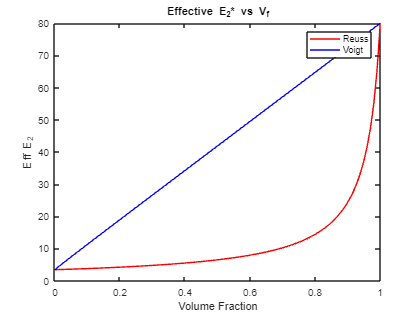


REff_E2 = double(subs(REff_E2,Vf,t));
plot(t,REff_E2,'r','Linewidth',0.2);
title("Effective E_2* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff E_2")
hold on
VEff_E2 = double(subs(VEff_E2,Vf,t));
plot(t,VEff_E2,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

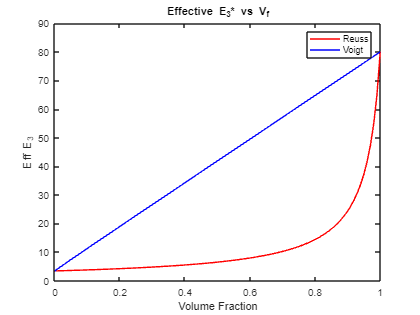


REff_E3 = double(subs(REff_E3,Vf,t));
plot(t,REff_E3,'r','Linewidth',0.2);
title("Effective E_3* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff E_3")
hold on
VEff_E3 = double(subs(VEff_E3,Vf,t));
plot(t,VEff_E3,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

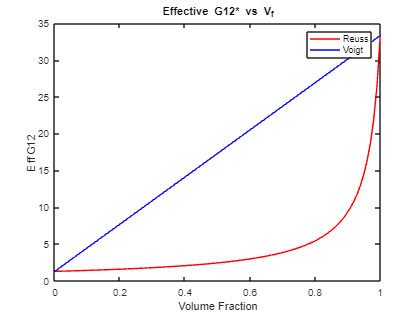


REff_G12 = double(subs(REff_G12,Vf,t));
plot(t,REff_G12,'r','Linewidth',0.2);
title("Effective G12* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff G12")
hold on
VEff_G12 = double(subs(VEff_G12,Vf,t));
plot(t,VEff_G12,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

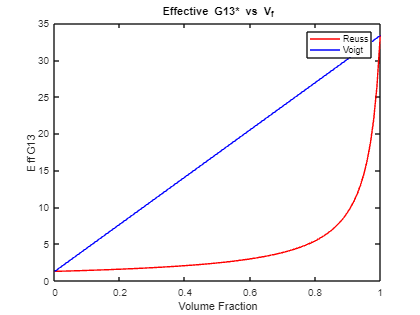


REff_G13 = double(subs(REff_G13,Vf,t));
plot(t,REff_G13,'r','Linewidth',0.2);
title("Effective G13* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff G13")
hold on
VEff_G13 = double(subs(VEff_G13,Vf,t));
plot(t,VEff_G13,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

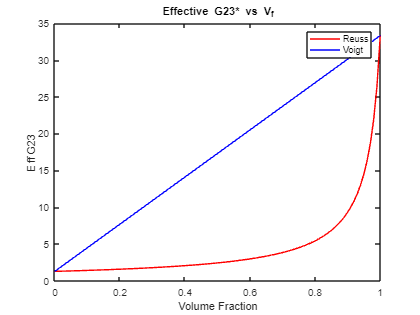

 
REff_G23 = double(subs(REff_G23,Vf,t));
plot(t,REff_G23,'r','Linewidth',0.2);
title("Effective G23* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff G23")
hold on
VEff_G23 = double(subs(VEff_G23,Vf,t));
plot(t,VEff_G23,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

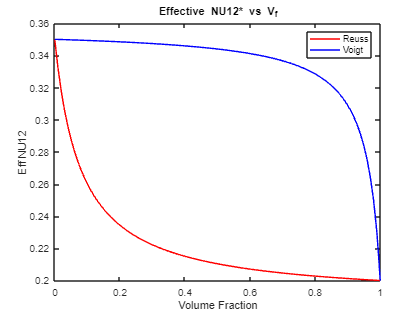


VEff_NU12 = double(subs(VEff_NU12,Vf,t));
plot(t,VEff_NU12,'r','Linewidth',0.2);
title("Effective NU12* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff NU12")
hold on
REff_NU12 = double(subs(REff_NU12,Vf,t));
plot(t,REff_NU12,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

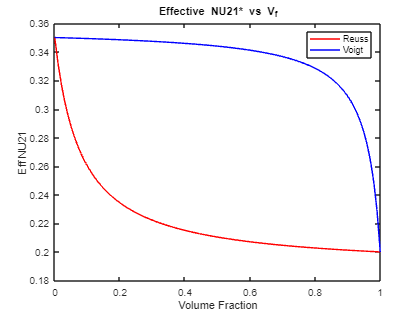


VEff_NU21 = double(subs(VEff_NU21,Vf,t));
plot(t,VEff_NU21,'r','Linewidth',0.2);
title("Effective NU21* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff NU21")
hold on
REff_NU21 = double(subs(REff_NU21,Vf,t));
plot(t,REff_NU21,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

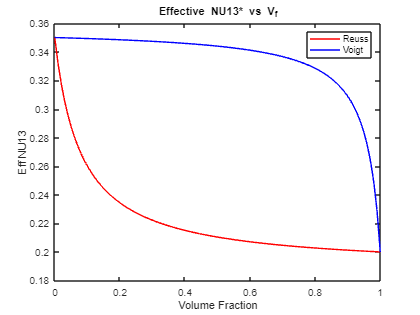


VEff_NU13 = double(subs(VEff_NU13,Vf,t));
plot(t,VEff_NU13,'r','Linewidth',0.2);
title("Effective NU13* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff NU13")
hold on
REff_NU13 = double(subs(REff_NU13,Vf,t));
plot(t,REff_NU13,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

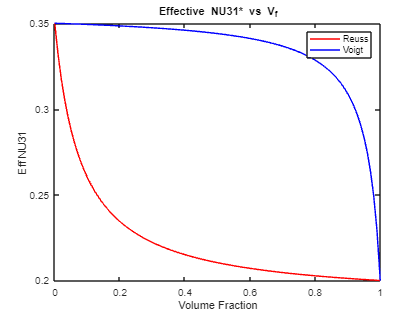


VEff_NU31 = double(subs(VEff_NU31,Vf,t));
plot(t,VEff_NU31,'r','Linewidth',0.2);
title("Effective NU31* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff NU31")
hold on
REff_NU31 = double(subs(REff_NU31,Vf,t));
plot(t,REff_NU31,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

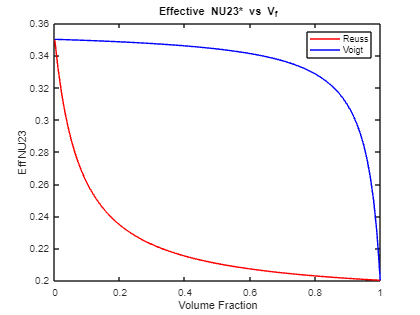


VEff_NU23 = double(subs(VEff_NU23,Vf,t));
plot(t,VEff_NU23,'r','Linewidth',0.2);
title("Effective NU23* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff NU23")
hold on
REff_NU23 = double(subs(REff_NU23,Vf,t));
plot(t,REff_NU23,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off

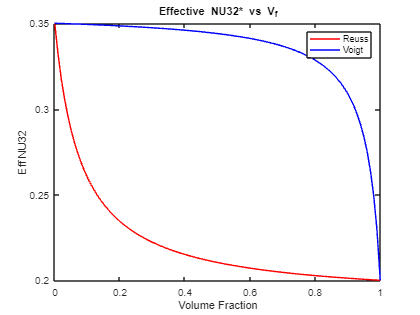


VEff_NU32 = double(subs(VEff_NU32,Vf,t));
plot(t,VEff_NU32,'r','Linewidth',0.2);
title("Effective NU32* vs V_f")
xlabel("Volume Fraction")
ylabel("Eff NU32")
hold on
REff_NU32 = double(subs(REff_NU32,Vf,t));
plot(t,REff_NU32,'b','Linewidth',0.2);
legend(["Reuss","Voigt"])
hold off